# **Report 3**

## **Pouya Abginechi - 40023001**

## **Alisina Shahmohammadi - 40023041**

#### **7. Aliasing in Frequency:**

resampling the sinc(5t)^5 with diffrent samping times and observing the effect it would have on the frequency spectrum 

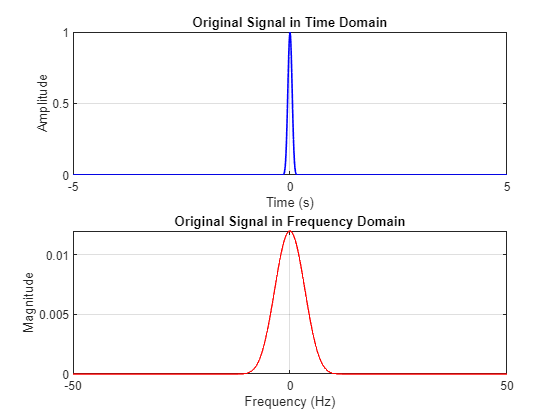

clc;
clear all;
close all;

% Time setup for the continuous signal
time_start = -5;
time_end = 5;
time_step = 0.01;
t_dense = time_start:time_step:time_end;

% Original continuous signal
signal_dense = (sinc(5 * t_dense)).^5;

% Plot the continuous signal
figure;
subplot(2,1,1);
plot(t_dense, signal_dense, 'b', 'LineWidth', 1.2);
title('Original Signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% Frequency domain of the original signal
signal_fft = fft(signal_dense);
N = length(signal_fft);
freq = (-N/2:N/2-1)*(1/time_step/N);

subplot(2,1,2);
plot(freq, abs(fftshift(signal_fft))/N, 'r');
title('Original Signal in Frequency Domain');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

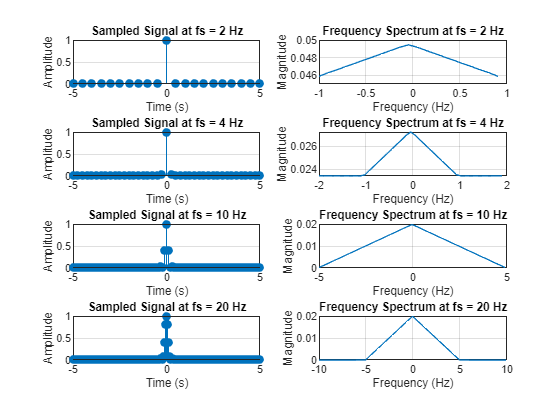


%% Sampling and frequency analysis at different sampling rates
sampling_rates = [2, 4, 10, 20];

figure;
for i = 1:length(sampling_rates)
    fs = sampling_rates(i);
    t_sample = time_start:1/fs:time_end;
    sampled_signal = (sinc(5 * t_sample)).^2;

    % Plot time domain
    subplot(length(sampling_rates), 2, 2*i-1);
    stem(t_sample, sampled_signal, 'filled');
    title(['Sampled Signal at fs = ' num2str(fs) ' Hz']);
    xlabel('Time (s)');
    ylabel('Amplitude');
    grid on;

    % FFT of sampled signal
    fft_sampled = fft(sampled_signal);
    N_sampled = length(fft_sampled);
    freq_sampled = (-N_sampled/2:N_sampled/2-1)*(fs/N_sampled);

    % Plot frequency domain
    subplot(length(sampling_rates), 2, 2*i);
    plot(freq_sampled, abs(fftshift(fft_sampled))/N_sampled);
    title(['Frequency Spectrum at fs = ' num2str(fs) ' Hz']);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    grid on;
end